**This Script does feature selection from visual memory face and visual memory face-name association **

**Then the clustering and classification of these features.**

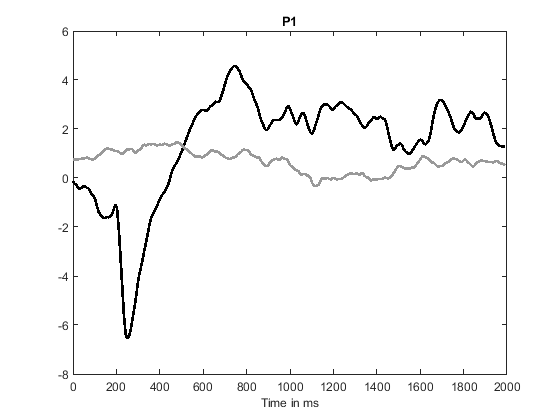

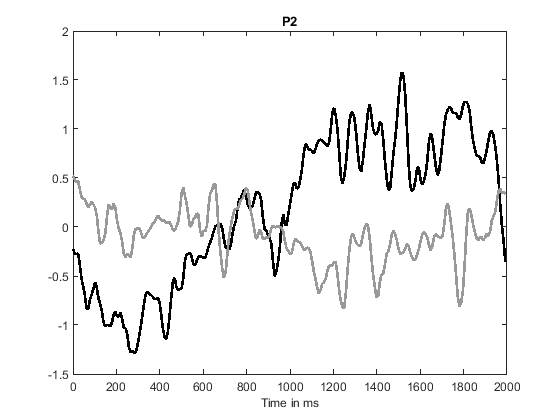

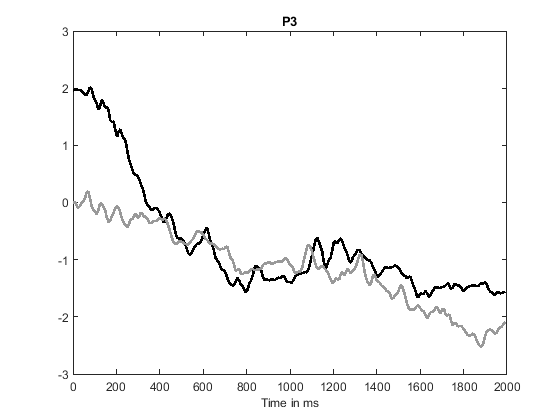

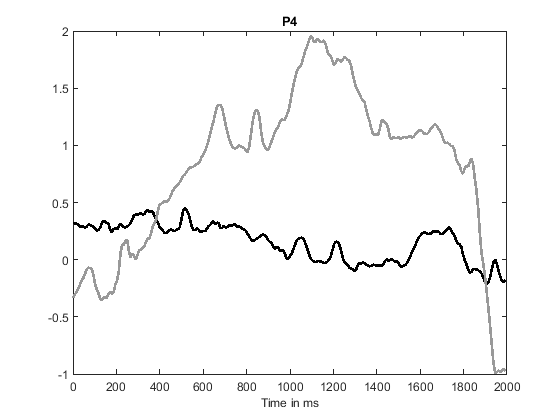

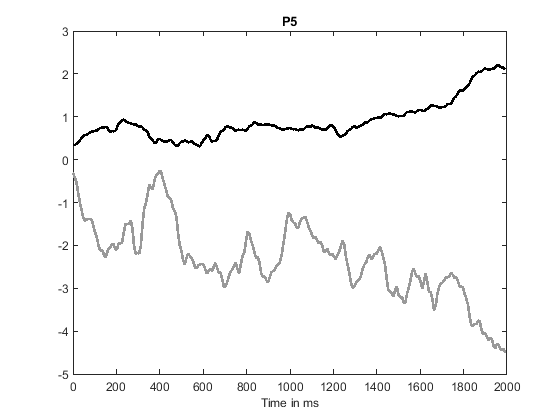

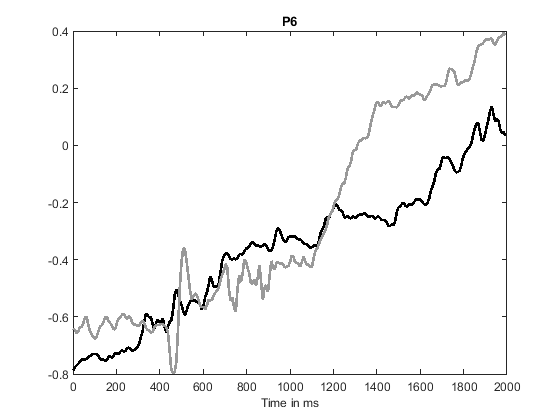

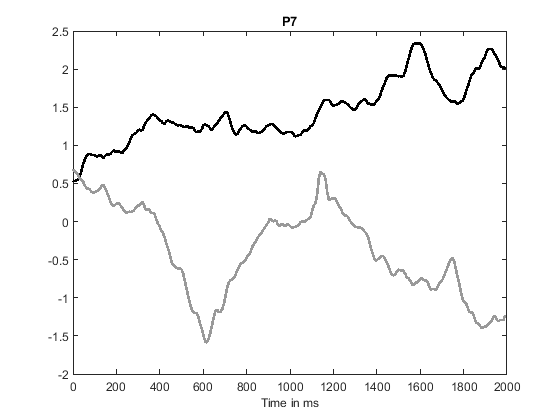

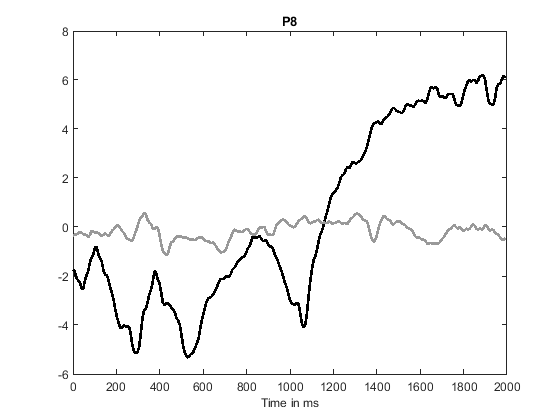

myLabels = load("Labels.mat").Labels;
myEEG = load("EEG_Datasets.mat").EEG;

headers = ["EEG.AF3","EEG.F7","EEG.F3","EEG.FC5","EEG.T7","EEG.P7","EEG.O1","EEG.O2","EEG.P8","EEG.T8","EEG.FC6","EEG.F4","EEG.F8","EEG.AF4"];
% this headers is 4  to 17 in EEG file 

trials = [];

Xf = 0:1000/128: 1999; % time vector
Nf = numel(Xf);

for x = 1:length(subs) % for each participant
    
    %base lined corrected individual trials
      trials(x).FaceOnly([4:17],:,:) = 100 * (myEEG(x).FaceOnly([4:17],:,:) - mean(myEEG(x).FOnlyBaseLine([4:17],:,:), 3, 'omitnan'))./mean(myEEG(x).FOnlyBaseLine([4:17],:,:), 3, 'omitnan');
      trials(x).Face_VisualName([4:17],:,:) = 100 * ((myEEG(x).Face_VisualName([4:17],:,:)) - mean(myEEG(x).FVisualBaseLine([4:17],:,:), 3, 'omitnan'))./ mean(myEEG(x).FVisualBaseLine([4:17],:,:), 3, 'omitnan');
    
   figure('Color','w','NumberTitle','off') % make blank figure
   hold on % we're going to plot several elements
   mych = 12; 
    for chann=mych:mych
      
       title(['P',num2str(x)],'FontSize', 5);  
       
       mm1 = squeeze(trials(x).FaceOnly(chann,:,1));
       mm2 = squeeze(trials(x).Face_VisualName(chann,:,1));
       plot(Xf,movmean(mm1, 5),'Color','black','LineStyle','-','LineWidth',2);
       plot(Xf,movmean(mm2, 5),'Color',[0.6 0.6 0.6],'LineStyle','-','LineWidth',2);
       
       set(gca,'LineWidth',1,'FontSize',9,'XLim',[0 2000]);
       xlabel('Time in ms','FontSize',9);
    
        box on
    end
   
    
end

**Now Extract ERP Components**

DatatoUse = [];
DataERPs1 = [];
DataERPs1 = [];
% N170, N200, P300, N400 and N500

 mych = 17; 
  
 for x = 1:length(subs) % for each participant
     
    for chann=mych:mych
        
       tr1 = size(squeeze(trials(x).FaceOnly(chann,:,:)), 2);
       tr2 = size(squeeze(trials(x).Face_VisualName(chann,:,:)), 2);
       
       for t1=1:tr1
           
            mm1 = squeeze(trials(x).FaceOnly(chann,:,t1));   
            %get N170
            DF1 = min(mm1(15:28));
            %get N200
            DF2 = min(mm1(19:32));
            %get P300
            DF3 = max(mm1(32:44));
            %get N400
            DF4 = min(mm1(44:57));
            %get N500
            DF5 = min(mm1(57:70));
            
            DataERPs1(t1,:) = [DF1 DF2 DF3 DF4 DF5 1];
            
            DF1 = ""; DF2="";DF3 =""; DF4 = ""; DF5="";
       end
       
       for t2=1:tr2
            mm2 = squeeze(trials(x).Face_VisualName(chann,:,t2));  
            %get N170
            DF1 = min(mm2(15:28));
            %get N200
            DF2 = min(mm2(19:32));
            %get P300
            DF3 = max(mm2(32:44));
            %get N400
            DF4 = min(mm2(44:57));
            %get N500
            DF5 = min(mm2(57:70));
            
            DataERPs2(t2,:) = [DF1 DF2 DF3 DF4 DF5 2];
            
            DF1 = ""; DF2="";DF3 =""; DF4 = ""; DF5="";
       end
       
    end
   
    

 
 DatatoUse = [DataERPs1;DataERPs2];
 DatatoUse = DatatoUse(randperm(size(DatatoUse, 1)), :)

DatatoUse =     -2.082021926349228e-01    -2.483460041705798e-01     7.369633827860652e-01     5.061015798722647e-01     4.331437855242262e-02     2.000000000000000e+00
     7.032559320432479e-02     7.032559320432479e-02     5.908386194923856e-01    -8.869710519473549e-02    -4.600350976633162e-01     1.000000000000000e+00
    -8.394845174343459e-01    -1.013371303026342e+00    -2.599938126641626e-01    -4.336946436969715e-01    -3.229056686707415e-02     2.000000000000000e+00
    -6.593521938534462e-02    -2.053786356996356e-01     3.306242953006919e-01    -3.521409377920526e-01    -4.442471991435402e-01     1.000000000000000e+00
    -1.972427398192322e-01    -1.972427398192322e-01     2.856320692734171e-01    -6.611925310621973e-02    -3.657936742106698e-01     1.000000000000000e+00
    -1.211629493347890e-01    -1.211629493347890e-01     9.578052748789392e-01    -2.067638372093371e-01    -8.697410466900700e-01     1.000000000000000e+00
     3.116640118660764e-01     2.7974996728034

BaggedEnsemble =   TreeBagger
Ensemble with 60 bagged decision trees:
                    Training X:              [120x5]
                    Training Y:              [120x1]
                        Method:       classification
                 NumPredictors:                    5
         NumPredictorsToSample:                    3
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'

  Properties, Methods


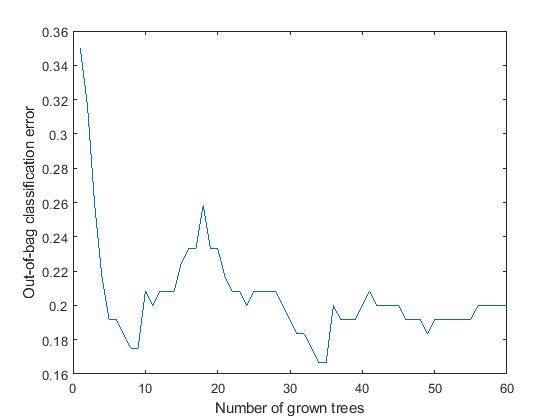

ans = 120×1 cell array
    {'2'}
    {'1'}
    {'2'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'2'}
    {'1'}
    {'1'}
    {'2'}
    {'2'}
    {'2'}
    {'2'}
    {'1'}
    {'2'}
    {'1'}
    {'1'}
    {'1'}
    {'2'}
    {'2'}
    {'1'}
    {'1'}
    {'2'}
    {'2'}
    {'2'}
    {'2'}
    {'1'}
    {'1'}


Decision tree for classification
 1  if x4<0.146418 then node 2 elseif x4>=0.146418 then node 3 else 2
 2  if x1<-0.471755 then node 4 elseif x1>=-0.471755 then node 5 else 1
 3  if x2<0.29005 then node 6 elseif x2>=0.29005 then node 7 else 2
 4  if x3<0.510669 then node 8 elseif x3>=0.510669 then node 9 else 2
 5  if x3<0.544668 then node 10 elseif x3>=0.544668 then node 11 else 1
 6  class = 2
 7  if x4<0.620814 then node 12 elseif x4>=0.620814 then node 13 else 2
 8  if x5<-0.533071 then node 14 elseif x5>=-0.533071 then node 15 else 2
 9  if x5<-0.272981 then node 16 elseif x5>=-0.272981 then node 17 else 1
10  if x5<-0.324986 then node 18 elseif x5>=-0.324986 then node 19 else 1
11  if x5<0.105429 then node 20 elseif x5>=0.105429 then node 21 else 1
12  if x4<0.489618 then node 22 elseif x4>=0.489618 then node 23 else 1
13  class = 2
14  if x1<-0.654745 then node 24 elseif x1>=-0.654745 then node 25 else 1
15  class = 2
16  class = 1
17  class = 2
18  if x1<0.241138 then node 26 e

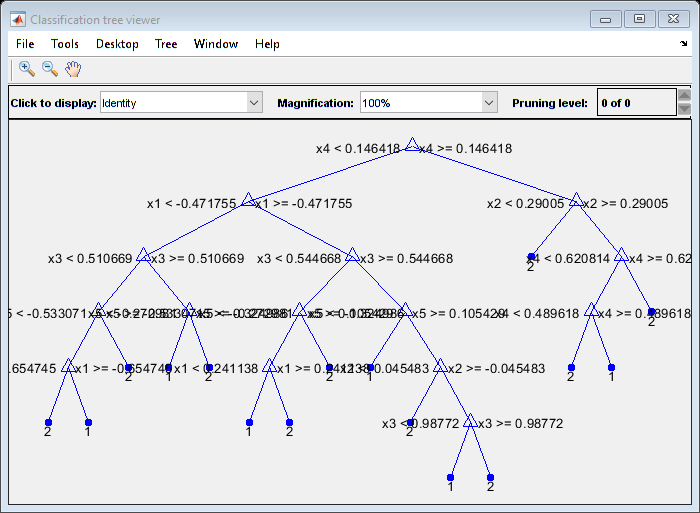

 X = DatatoUse([1:120],[1:5]);
 Y = DatatoUse([1:120],6);
 BaggedEnsemble = generic_random_forests(X,Y,60,'classification');

% 
 preds = predict(BaggedEnsemble,DatatoUse([121:end],[1:5]));
 actuallabs = DatatoUse([121:end],6);
 
 C = confusionmat(num2str(actuallabs), preds);

C =     30     5
     5    30


 
 acc = sum(diag(C))/sum(C(:));
 
 disp('Classification ' + acc);
 
 end